# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/16*pi)*s + 0.3)/((1/64*pi)*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

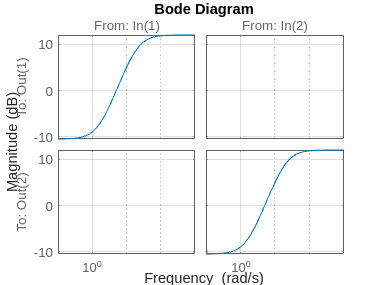

% frequency response of uncertainty weights
figure
bodemag(wi)
grid on

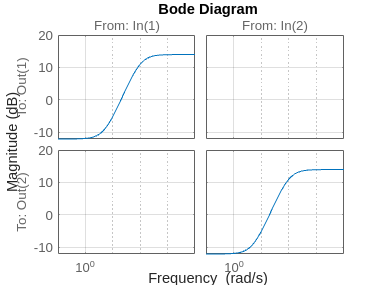


figure
bodemag(wo)
grid on

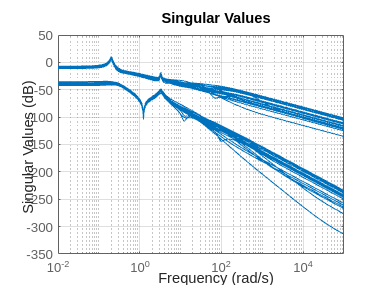


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2);
pb2 = ultidyn("odelta", 2);

wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wid)*G*(eye(2)+wod);

figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wu, wp, wo, wi, sumblock1, sumblock2, sumblock3, {'du', 'dy', 'w', 'u'}, {'di', 'do', 'z1', 'z2', 'v'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms

K = MS_C;

% NS - generalised Nyquist
ol = K*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

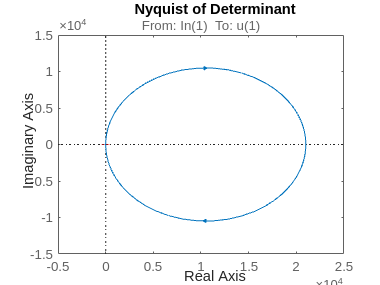


nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS
N = lft(dP, K);
M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,70);
Mf=frd(M,omega);
blockstructure =  ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 70/70



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 1.1498


% 
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 70/70



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.5490

%D-K iterations

Delta=[ultidyn('D_1',[1,1]) 0 0 0; 0 ultidyn('D_2',[1,1]) 0 0; 0 0 ultidyn('D_3',[1,1]) 0; 0 0 0 ultidyn('D_4',[1,1])];

Punc=lft(Delta,dP);

[DK, clp, dkinfo]=musyn(Punc,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           12.78        9.344        9.442            22
    2           6.681        6.536         6.58            16
    3           2.563        2.294        2.322            32
    4            1.31        1.309        1.425            28
    5           1.197        1.196         1.22            32
    6            1.17        1.169        1.188            32
    7           1.165        1.165         1.19            32
    8           1.164        1.162        1.185            32

Best achieved robust performance: 1.16



% RS and RP of DK
N = lft(dP, DK);
M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,100);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 100/100



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.7875


% RP
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 100/100



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.1552